load resnet_18\resnet.mat
signds = imageDatastore("D:\college\FYP\Experimenting\test\no-parking","IncludeSubfolders",true,"LabelSource","foldernames");
signNames = signds.Labels;
[signTrain,signTest] = splitEachLabel(signds,0.8,"randomized");

% Augmentation
resizeTrainImgs = augmentedImageDatastore([224 224],signTrain);
resizeTestImgs = augmentedImageDatastore([224 224],signTest);

numClasses = numel(categories(signds.Labels));

% Setting Options
opts = trainingOptions("sgdm","InitialLearnRate",0.001,"MaxEpochs",5,"VerboseFrequency",2);

% Training the network
[Network1,info] = trainNetwork(resizeTrainImgs,resnet,opts);

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:33 |       52.00% |       1.3095 |          0.0010 |
|       2 |           2 |       00:01:04 |       53.00% |       1.1392 |          0.0010 |
|       4 |           4 |       00:02:08 |       70.00% |       0.5572 |          0.0010 |
|       5 |           5 |       00:02:41 |       85.00% |       0.3482 |          0.0010 |
|========================================================================================|
Training finished: Max epochs completed.


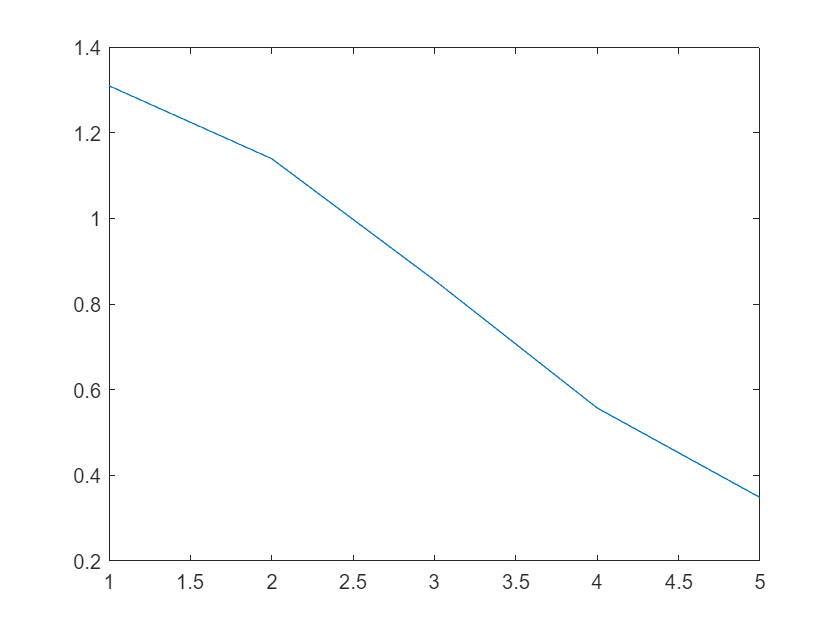


% Evaluating Performance
plot(info.TrainingLoss);

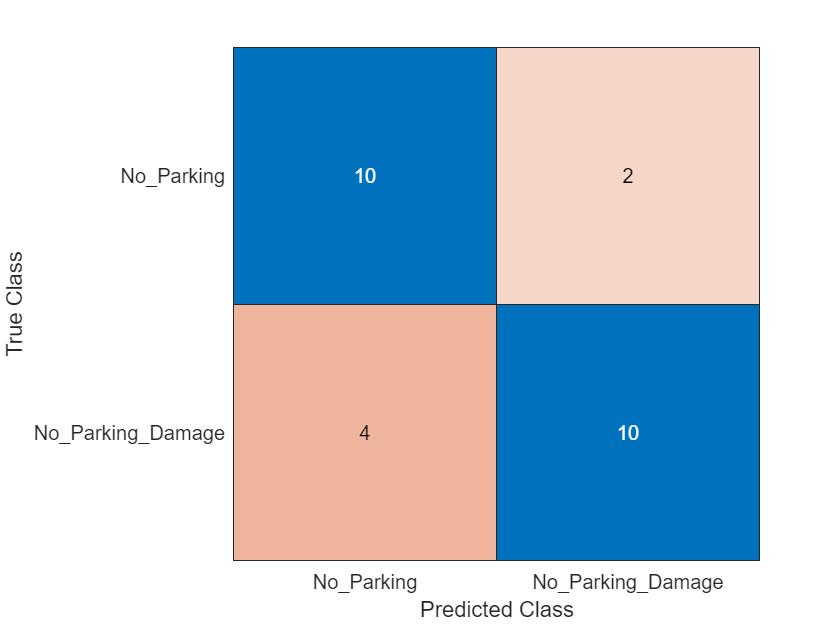



% Prediction
signPrediction = classify(Network1,resizeTestImgs);

signActual = signTest.Labels;

% Comparison
numCorrect = nnz(signPrediction == signActual);
fracCorrect = numCorrect/numel(signPrediction);

% Confusion Chart
confusionchart(signActual,signPrediction);